
data_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\regbot_log_6_wd.txt');
data_wd = fillmissing(data_wd, 'nearest');

[t_wd,u_L_wd,u_R_wd,v_L_wd,v_R_wd,T_s_wd] = get_data(data_wd);

idd_L_wd = iddata(v_L_wd,u_L_wd,T_s_wd);

G_L_wd = tfest(idd_L_wd,2,0) 

G_L_wd =
 
  From input "u1" to output "y1":
         38.57
  -------------------
  s^2 + 34.84 s + 148
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "idd_L_wd".
Fit to estimation data: 92.25%                       
FPE: 0.001276, MSE: 0.001268                         


[num, denom] = tfdata(G_L_wd); 
Kp = 5;
num = cell2mat(num)

num =          0         0   38.5679


denom = cell2mat(denom)

denom =     1.0000   34.8352  148.0277


simout = sim('C:\Users\Alonso\Desktop\REGBOT\Ex_8\simulink_model', 5); % simulate  for 5 seconds
plot(simout);

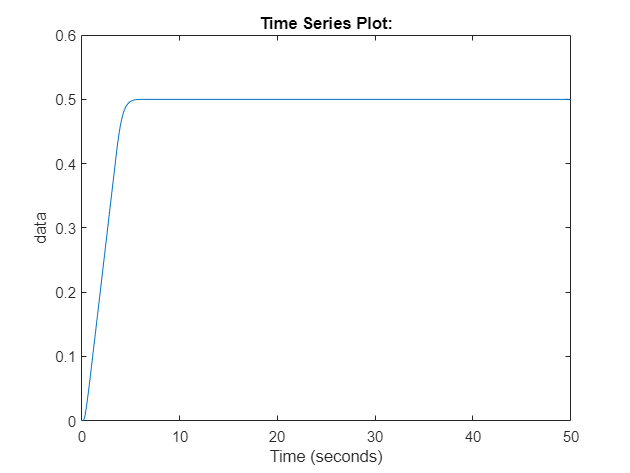

regbot_sim = sim("C:\Users\Alonso\Desktop\REGBOT\Ex_8\simulink_model", 50); % model_name is what you use for your own simulink model
plot(regbot_sim.simout);

bode()

function [t,u_L,u_R,v_L,v_R,T_s] = get_data(data)
    t = table2array(data(:,1));     % time stamps
    u_L = table2array(data(:,8));   % left motor voltage
    u_R = table2array(data(:,9));   % right motor voltage
    v_L = table2array(data(:,10));  % left motor velocity 
    v_R = table2array(data(:,11));  % right motor velocity
    T_s = t(2) - t(1);              % compute sampling time
end

